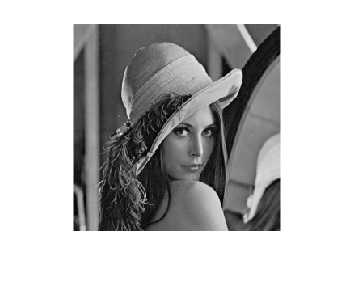

image=imread('lena.bmp');
imshow(image);

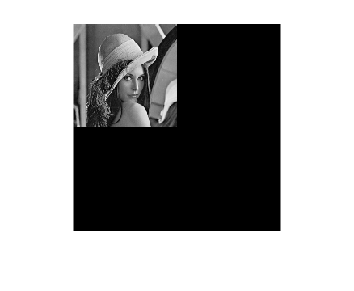


%subsample
subsampleImage=subsample(image,2);
imshow(subsampleImage,[]);

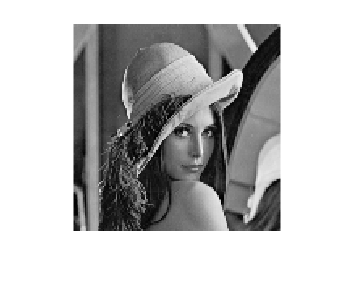


%supersample
supersampleImage=supersample(subsampleImage,2);
imshow(supersampleImage,[]);

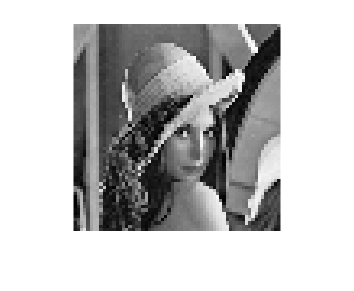


%subsample-subsample-supersample-supersample
tempimg1 = subsample(image,2);
tempimg2 = subsample(tempimg1,2);
tempimg3 = supersample(tempimg2,2);
image1 = supersample(tempimg3,2);
imshow(image1, []);

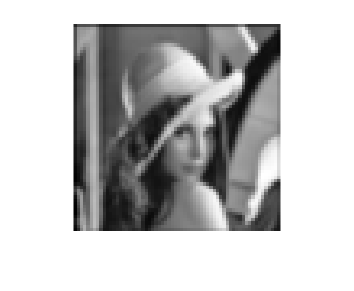


%GaussianSubsample-GaussianSubsample-supersample-supersample
tempimg4 = GaussianSubsample(image,2);
tempimg5 = GaussianSubsample(tempimg4,2);
tempimg6 = supersample(tempimg5,2);
image2 = supersample(tempimg6,2);
imshow(image2, []);

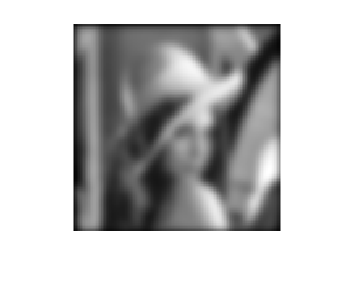


%GaussianSubsample-GaussianSubsample-GaussianSupersample-GaussianSupersample
tempimg7 = GaussianSubsample(image,2);
tempimg8 = GaussianSubsample(tempimg7,2);
tempimg9 = GaussianSupersample(tempimg8,2);
image3 = GaussianSupersample(tempimg9,2);
imshow(image3, []);

function subsampleImage=subsample(image,sampleRate)
        [height,width]=size(image);
        subsampleHeight=ceil(height/sampleRate);
        subsampleWidth=ceil(width/sampleRate);
        subsampleImage=zeros(height,width);
        heightIndex=1:sampleRate:height;
        widthIndex=1:sampleRate:width;
         
        for i=1:subsampleHeight
            subsampleImage(i,1:subsampleWidth)=image(heightIndex(i),widthIndex);
        end

end

function supersampleImage=supersample(image,sampleRate)
        [height,width]=size(image);
        supersampleImageX=zeros(height*sampleRate,width*sampleRate);
        supersampleImage=zeros(height*sampleRate,width*sampleRate);

        for a=1:sampleRate
            for i=1+a-1:sampleRate:width*sampleRate
                supersampleImageX(1:height,i)=image(:,(i+(sampleRate-a))/sampleRate);
            end
        end

        for a=1:sampleRate
            for j=1+a-1:sampleRate:width*sampleRate
                supersampleImage(j,:)=supersampleImageX((j+(sampleRate-a))/sampleRate,:);
            end
        end
        supersampleImage=supersampleImage(1:height,1:width);
end

function GaussianSubsampleImage=GaussianSubsample(image,sampleRate)
        w=7;
        sigma=w/6;
        Gaussian_filter=fspecial('gaussian',w,sigma);
        smoothed=conv2(image,Gaussian_filter,'same');
        GaussianSubsampleImage=subsample(smoothed,sampleRate);
end

function GaussianSupersampleImage=GaussianSupersample(image,sampleRate)
        w=7;
        sigma=w/6;
        Gaussian_filter=fspecial('gaussian',w,sigma);
        smoothed=conv2(image,Gaussian_filter,'same');
        GaussianSupersampleImage=supersample(smoothed,sampleRate);
end